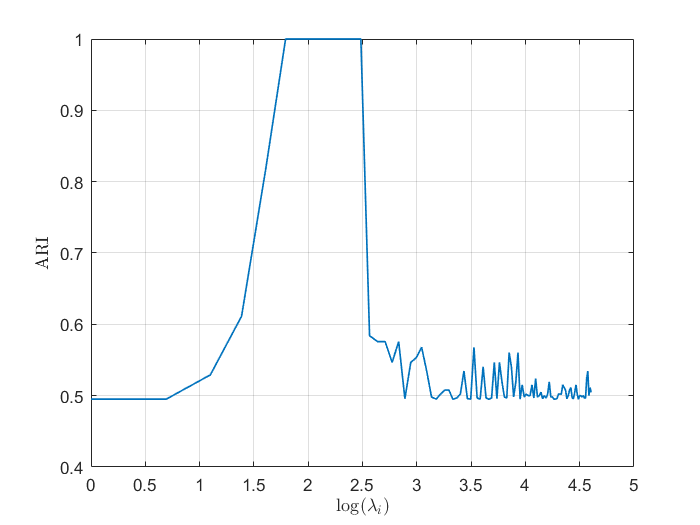

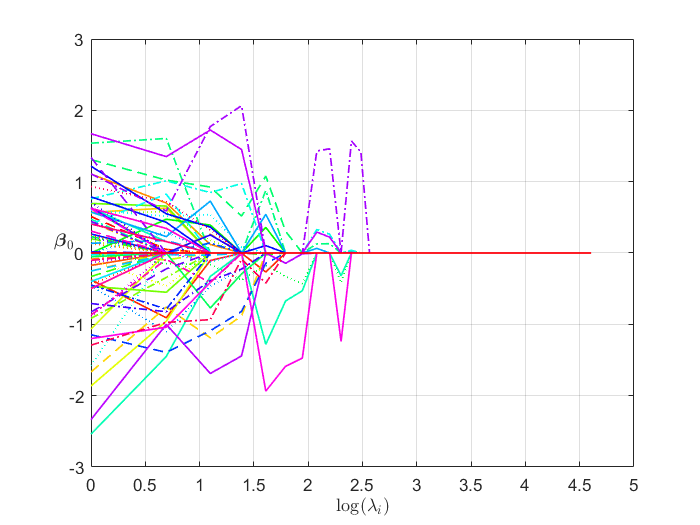

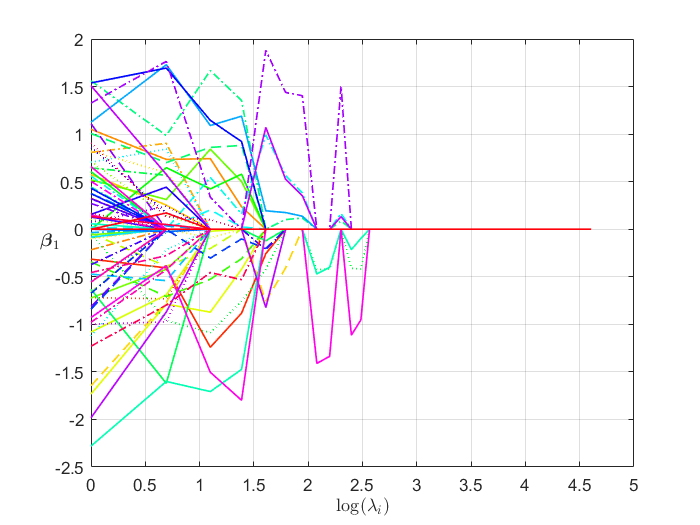

clc; clear; clf;
load("draw.mat");
lambda = linspace(0, 100, 101);
x0 = log(lambda);
plot(x0, ARI, "LineWidth", 1)
txt = xlabel('log($\lambda_i$)');
set(txt, 'Interpreter', 'latex');
txt = ylabel('ARI');
set(txt, 'Interpreter', 'latex');
grid on

% Create a new figure window
figure;
colors = hsv(151);

% Define 10 different line styles
line_styles = {'-', '--', ':', '-.', '-', '--', ':', '-.', '-', '-'};

% Create 150 different line style combinations
num_line_styles = numel(line_styles);
num_colors = size(colors, 1);

line_styles_combined = cell(1, num_colors);
for i = 1:num_colors
    line_styles_combined{i} = line_styles{mod(i-1, num_line_styles)+1};
end

% Loop to plot each curve corresponding to the x-axis
for i = 1:151
    plot(tt, draw_b1(:, i), 'Color', colors(i, :), 'LineStyle', line_styles_combined{i}, "LineWidth", 1);
    hold on;
end
grid on;
txt = xlabel('log($\lambda_i$)');
set(txt, 'Interpreter', 'latex');
txt = ylabel('\boldmath{$\beta$}\unboldmath{$_0$}');
set(txt, 'Interpreter', 'latex', 'Rotation', 0);
% Adjust the axis
hold off

% Loop to plot each curve corresponding to the x-axis
for i = 1:151
    plot(tt, draw_b2(:, i), 'Color', colors(i, :), 'LineStyle', line_styles_combined{i}, "LineWidth", 1);
    hold on;
end
grid on;
txt = xlabel('log($\lambda_i$)');
set(txt, 'Interpreter', 'latex');
txt = ylabel('\boldmath{$\beta$}\unboldmath{$_1$}');
set(txt, 'Interpreter', 'latex', 'Rotation', 0);
% Adjust the axis
hold off